addpath('Classes')


%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',true);
sympref('TypesetOutput',true);


# **Ball Plate Kinetics Revisited**

This script revisits the kinetics of the ball and plate system. Moments are taken about different locations than previous and the plate kinetics are considered with a friction and normal force acting rather than in the context of the compound system. The idea of bringing out the normal force explicitly as a form of actuation on the ball is considered here. For all the following analysis, the linear acceleration of the ball will be kept general, and in the frame of the plate for now. These must later be related to the state variables previously defined for the system in order to measure these global values. MAY ACTUALLY JUST START WITH THE GLOBAL ACCELERATION VECTOR IN TERMS OF THE STATE VARIABLES. Intermediate decoupling steps are taken to make the model effectively two decoupled teeter totters.

%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

%Create a u-joint Kinematics object if one does not already exist. 
if (~exist('UJ_Knmtcs', 'var')) 

    UJ_Knmtcs = UJ_Knmtcs(VDefs); %Create an object of the class UJ_Knmtcs
    UJ_Knmtcs.derive_all; %Run all of its derivation functions

end 

%Create a ball-plate kinematics object if one does not already exist. 
if (~exist('BP_Knmtcs', 'var')) 

    BP_Knmtcs = BP_Knmtcs(VDefs, UJ_Knmtcs); %Create an object of the class BP_Knmtcs
    BP_Knmtcs.Derive_Both; %Derive all the kinematic equations for the ball-plate system
end 

%Create a ball-plate kinetics object if one does not already exist. 
if (~exist('BP_Kinetics', 'var')) 

    BP_Kinetics = BP_Kinetics(VDefs, UJ_Knmtcs, BP_Knmtcs); %Create an object of the class BP_Kinetics

end 

%Derive the Nonlinear Equations of motion in one go. Then generate the EOMs with numerical
%parameters filled in
BP_Kinetics.Derive_NL_EOMs;
BP_Kinetics.Num_Params_n_Assumptions;

%Create a linearized EOMs object if one does not already exist. 
if (~exist('Lnrzed_EOMs', 'var')) 

    Lnrzed_EOMs = Lnrzed_EOMs(VDefs, BP_Kinetics); %Create an object of the class Lnrzed_EOMs
end 


%Derive the 8th order linear model of the system about the unstable equilibrium point
Lnrzed_EOMs.Derive_8th_Ordr_Lin_Sys;

%Derive the two uncoupled 4th order linear systems
Lnrzed_EOMs.Derive_4th_Ordr_Lin_Sys;

## Kinetics of the Ball Alone

Define global kinematic variables - keep general for now. Can transform into measureable state variables later.

syms Hb_x Hb_dot_x Hb_y Hb_dot_y Hb_z Hb_dot_z r_x r_y r_z a_x a_y a_z

rb0s = [r_x;r_y;r_z]

$$rb0s = \left[\begin{array}{c} r_{x}\\ r_{y}\\ r_{z} \end{array}\right]$$

ab0s = [a_x; a_y; a_z]

$$ab0s = \left[\begin{array}{c} a_{x}\\ a_{y}\\ a_{z} \end{array}\right]$$

Hb0s = [Hb_x; Hb_y; Hb_z]

$$Hb0s = \left[\begin{array}{c} {\mathrm{Hb}}_{x}\\ {\mathrm{Hb}}_{y}\\ {\mathrm{Hb}}_{z} \end{array}\right]$$

Hb0ds = [Hb_dot_x; Hb_dot_y; Hb_dot_z]

$$Hb0ds = \left[\begin{array}{c} {\dot{\mathrm{Hb}}}_{x}\\ {\dot{\mathrm{Hb}}}_{y}\\ {\dot{\mathrm{Hb}}}_{z} \end{array}\right]$$

## 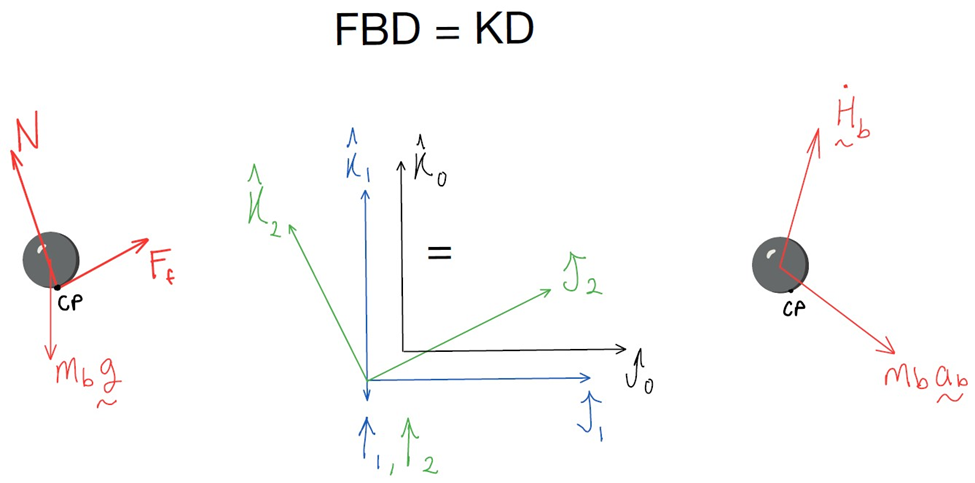

### Sum of Moments About Center of Mass of the Ball

The moment arm to the contact point here is the radius of the ball $r_b$ in the plate's negative z-direction as before


$$-arm_b^{(2)} = \left\lbrack \begin{array}{c}
0\\
0\\
-r_b 
\end{array}\right\rbrack$$


The sum of moments about the ball's center of gravity on the free body diagram is equal to the sum of the moments about the same point on the kinetic diagram. 


$$

\begin{array}{rl}

\sum{M_{cg~FBD} &=~~ \sum{M_{cg~KD}\\[6pt]

R^{20}(-arm^{(2)}_b \times F_f)

&=~~  

\dot{H}^{(0)}_b

\end{array}$$


Resulting in a set of moment equations

SumMBall = expand(VDefs.R20*(cross(-VDefs.armb2s, VDefs.F_f))) == Hb0ds;
SumMBall = subs(SumMBall, VDefs.symFunVec, VDefs.symVarVec)

$$SumMBall = \left[\begin{array}{c} f_{y}\,r_{b}\,\cos\left(\beta \right)-f_{x}\,r_{b}\,\sin\left(\beta \right)\,\sin\left(\gamma \right)={\dot{\mathrm{Hb}}}_{x}\\ -f_{x}\,r_{b}\,\cos\left(\gamma \right)={\dot{\mathrm{Hb}}}_{y}\\ -f_{y}\,r_{b}\,\sin\left(\beta \right)-f_{x}\,r_{b}\,\cos\left(\beta \right)\,\sin\left(\gamma \right)={\dot{\mathrm{Hb}}}_{z} \end{array}\right]$$

Which can be decoupled from the $y$ and $\gamma$ states by assuming they are all zero. 

SumMBall = subs(SumMBall, [VDefs.gamma VDefs.gamma_dot VDefs.gamma_ddot VDefs.y VDefs.y_dot VDefs.y_ddot VDefs.psi_z VDefs.psi_dot_z VDefs.f_y],...
 [0 0 0 0 0 0 0 0 0])

$$SumMBall = \left[\begin{array}{c} 0={\dot{\mathrm{Hb}}}_{x}\\ -f_{x}\,r_{b}={\dot{\mathrm{Hb}}}_{y}\\ 0={\dot{\mathrm{Hb}}}_{z} \end{array}\right]$$

f_x = rhs(isolate( SumMBall(2),VDefs.f_x)) %Substituted into the force equations below

$$f\_x = -\frac{{\dot{\mathrm{Hb}}}_{y}}{r_{b}}$$

### Sum of Forces for the Ball


$$

\begin{array}{rl}

\sum{F_{FBD} &=~~ \sum{F_{KD}\\[6pt]

R^{20}(F_f + N) + W^{(0)}_b 

&=~~  

m_b a^{(0)}_b

\end{array}$$


SumFBall = VDefs.R20*(VDefs.F_f + VDefs.N) + VDefs.Wb0s == VDefs.m_b*ab0s;
SumFBall = subs(SumFBall, VDefs.symFunVec, VDefs.symVarVec)

$$SumFBall = \left[\begin{array}{c} f_{x}\,\cos\left(\beta \right)+N_{z}\,\cos\left(\gamma \right)\,\sin\left(\beta \right)+f_{y}\,\sin\left(\beta \right)\,\sin\left(\gamma \right)=a_{x}\,m_{b}\\ f_{y}\,\cos\left(\gamma \right)-N_{z}\,\sin\left(\gamma \right)=a_{y}\,m_{b}\\ N_{z}\,\cos\left(\beta \right)\,\cos\left(\gamma \right)-f_{x}\,\sin\left(\beta \right)-g\,m_{b}+f_{y}\,\cos\left(\beta \right)\,\sin\left(\gamma \right)=a_{z}\,m_{b} \end{array}\right]$$

Which can be decoupled from the $y$ and $\gamma$ states by assuming they are all zero. 

SumFBall = subs(SumFBall, [VDefs.gamma VDefs.gamma_dot VDefs.gamma_ddot VDefs.y VDefs.y_dot VDefs.y_ddot VDefs.psi_z VDefs.psi_dot_z VDefs.f_y],...
 [0 0 0 0 0 0 0 0 0])

$$SumFBall = \left[\begin{array}{c} N_{z}\,\sin\left(\beta \right)+f_{x}\,\cos\left(\beta \right)=a_{x}\,m_{b}\\ 0=a_{y}\,m_{b}\\ N_{z}\,\cos\left(\beta \right)-g\,m_{b}-f_{x}\,\sin\left(\beta \right)=a_{z}\,m_{b} \end{array}\right]$$

Substitute in the expression for the friction force

SumFBall = subs(SumFBall, VDefs.f_x, f_x)

$$SumFBall = \left[\begin{array}{c} N_{z}\,\sin\left(\beta \right)-\frac{{\dot{\mathrm{Hb}}}_{y}\,\cos\left(\beta \right)}{r_{b}}=a_{x}\,m_{b}\\ 0=a_{y}\,m_{b}\\ N_{z}\,\cos\left(\beta \right)-g\,m_{b}+\frac{{\dot{\mathrm{Hb}}}_{y}\,\sin\left(\beta \right)}{r_{b}}=a_{z}\,m_{b} \end{array}\right]$$

## Kinetics of Plate Alone

Sum Moments About Center of U-Joint in the S1 Frame (want U-Joint torques to be easy)

y = [1 0 0]*VDefs.R20*[VDefs.x_hat; VDefs.y_hat; VDefs.z_b] %Extract out global x location as our output to control

$$y(t) = \cos\left(\hat{\beta }\left(t\right)\right)\,\hat{x}\left(t\right)+z_{b}\,\cos\left(\hat{\gamma }\left(t\right)\right)\,\sin\left(\hat{\beta }\left(t\right)\right)+\sin\left(\hat{\beta }\left(t\right)\right)\,\sin\left(\hat{\gamma }\left(t\right)\right)\,\hat{y}\left(t\right)$$


y_dcpld = subs(y, VDefs.gamma_hat, 0)

$$y\_dcpld(t) = z_{b}\,\sin\left(\hat{\beta }\left(t\right)\right)+\cos\left(\hat{\beta }\left(t\right)\right)\,\hat{x}\left(t\right)$$


yd_dcpled = diff(y_dcpld, VDefs.t)

$$yd\_dcpled(t) = \cos\left(\hat{\beta }\left(t\right)\right)\,\frac{\partial }{\partial t}\hat{x}\left(t\right)-\sin\left(\hat{\beta }\left(t\right)\right)\,\hat{x}\left(t\right)\,\frac{\partial }{\partial t}\hat{\beta }\left(t\right)+z_{b}\,\cos\left(\hat{\beta }\left(t\right)\right)\,\frac{\partial }{\partial t}\hat{\beta }\left(t\right)$$

ydd_dcpled = diff(y_dcpld, VDefs.t,2)

$$ydd\_dcpled(t) = \cos\left(\hat{\beta }\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\hat{x}\left(t\right)-2\,\sin\left(\hat{\beta }\left(t\right)\right)\,\frac{\partial }{\partial t}\hat{x}\left(t\right)\,\frac{\partial }{\partial t}\hat{\beta }\left(t\right)-z_{b}\,\sin\left(\hat{\beta }\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\hat{\beta }\left(t\right)\right)}^{2}+z_{b}\,\cos\left(\hat{\beta }\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\hat{\beta }\left(t\right)-\cos\left(\hat{\beta }\left(t\right)\right)\,\hat{x}\left(t\right)\,{\left(\frac{\partial }{\partial t}\hat{\beta }\left(t\right)\right)}^{2}-\sin\left(\hat{\beta }\left(t\right)\right)\,\hat{x}\left(t\right)\,\frac{\partial^{2}}{\partial t^{2}}\hat{\beta }\left(t\right)$$


y_lin = subs(y,[VDefs.gamma_hat sin(VDefs.beta_hat) cos(VDefs.beta_hat)], [0 VDefs.beta_hat 1])

$$y\_lin(t) = \hat{x}\left(t\right)+z_{b}\,\hat{\beta }\left(t\right)$$

yd_lin = diff(y_lin, VDefs.t)

$$yd\_lin(t) = z_{b}\,\frac{\partial }{\partial t}\hat{\beta }\left(t\right)+\frac{\partial }{\partial t}\hat{x}\left(t\right)$$

ydd_lin = diff(y_lin, VDefs.t, 2)

$$ydd\_lin(t) = z_{b}\,\frac{\partial^{2}}{\partial t^{2}}\hat{\beta }\left(t\right)+\frac{\partial^{2}}{\partial t^{2}}\hat{x}\left(t\right)$$

ydd_lin = subs(ydd_lin, VDefs.symFunVec, VDefs.symVarVec)

$$ydd\_lin(t) = \ddot{x}+\ddot{\beta }\,z_{b}$$

ydd_lin = expand(subs(ydd_lin, [VDefs.x_ddot VDefs.beta_ddot], [rhs(Lnrzed_EOMs.Lin_EOMs1(2)) rhs(Lnrzed_EOMs.Lin_EOMs1(4)) ]))

$$ydd\_lin(t) = 112.8871\,x\,z_{b}-5.2170\,x+64.8295\,\beta \,z_{b}+383.5785\,T_{\beta }\,z_{b}+4.0111\,\beta -17.7268\,T_{\beta }$$

xdd_lin = rhs(Lnrzed_EOMs.Lin_EOMs1(2))

$$xdd\_lin = -5.2170\,x+4.0111\,\beta -17.7268\,T_{\beta }$$

% ydot = diff(y,VDefs.t,1)
% yddot = diff(y,VDefs.t,2)
% yddot = subs(yddot, VDefs.symFunVec, VDefs.symVarVec)
% %Sub in for x_ddot and beta_ddot from nonlinear numerical equations of motion
% yddot = subs(yddot, [VDefs.x_ddot VDefs.beta_ddot], [rhs(BP_Kinetics.NL_NumEOMs(2)) rhs(BP_Kinetics.NL_NumEOMs(4))])

% 
% %Decouple
% yddot = expand(subs(yddot, [VDefs.gamma VDefs.gamma_dot VDefs.gamma_ddot VDefs.y VDefs.y_dot VDefs.y_ddot VDefs.psi_z VDefs.psi_dot_z VDefs.f_y],...
%  [0 0 0 0 0 0 0 0 0]))
